# MATLAB软件入门分析

Date：2023年3月13日

Author：Evand

## 入门综述

使用matlab编程时，通常使用.m文件，把所有代码编好后，统一运行or调试。如果想运行一两行代码，可以使用“命令行窗口”，一般在MATLAB主窗口的下方。

本文件是.mlx的实时编辑脚本文件，可以理解成介于.m文件和命令行之间的东西，将文本（据说兼容latex）与代码结合，可以实时调试，所以实时性很高，但是也因此对电脑的性能要求稍微高一点。

下面打一个hello MATLAB的代码，并显示出来：

disp('hello MATLAB');

hello MATLAB


此时，可以按一下F5或点一下上方的“运行”，能看见hello MATLAB直接显示在上面那一行代码的下面（也可以调整到右侧）了。

## 绘图

绘图最常用的是plot（绘制曲线图），但是就算是plot也有很多种搭配，比如想画一条直线，从（1,2）到（3,4），可以像下面这样先设定两个向量：

a = [1,3];
b = [2,4];

然后将a向量作为横坐标，b向量作为纵坐标，用plot绘制即可，为了防止图像之间互相干扰，可以在代码前面加一个"figure"，以生成一个新的图画：

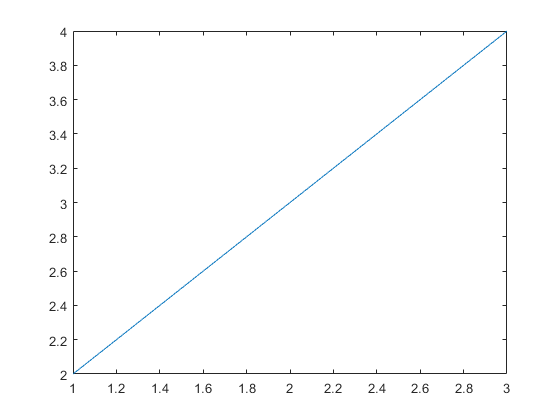

figure;
plot(a,b);

但是此时可能还想打上横纵坐标的值：

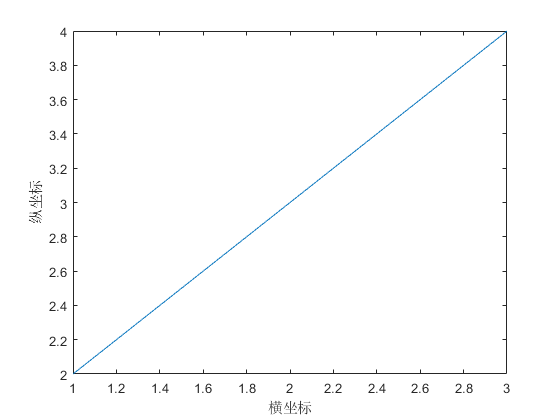

figure;
plot(a,b);
xlabel('横坐标');
ylabel('纵坐标');

如果还想加上标题，则用"title('标题');"即可。

## 运算

正常的加减乘除都跟c语言一样，对于矩阵运算，点乘是.*，矩阵相乘是*

对于一个矩阵A，如果要提取它的第一行第一列的元素，则用A(1,1);

如果要提取第1~3行，则用A(1:3,:);

A = [1,2,3,4;5,6,7,8;9,1,2,3;4,5,6,7];
A(1,1) %代码后面不加冒号，运算后会直接输出结果

ans =      1


A(1:3,:)

ans =      1     2     3     4
     5     6     7     8
     9     1     2     3


if-else示例：

if 1>3
    disp('1>3');
else
    disp('1 <= 3');
end

1 <= 3


for循环：循环次数用冒号结构，循环体以end结尾

a=1;
for i=1:30
    a = a+1;
end
disp(a);

    31



## 卡尔曼滤波运用

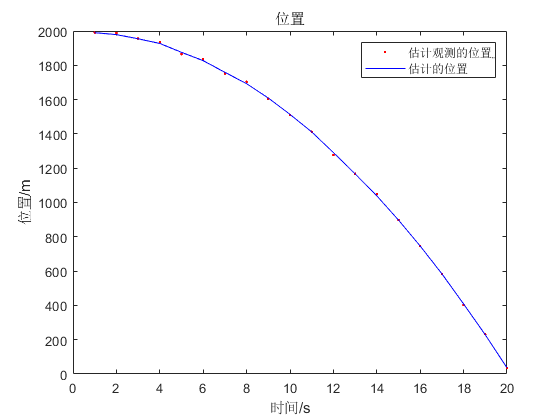

% edited by JBR
% data. 2020.5.1
% 自由落体卡尔曼例程
clear;clc;
i1 = 1:20;
% 录入观测值（单位为是km）
% Z = [1.9945,1.9794,1.9554,1.9214,1.8777,1.8250,1.7598,1.6867,1.6036,...
%     1.5092,1.4076,1.2944,1.1724,1.0399,0.8980,0.7455,0.5850,0.4125,0.2318,0.0399];
height = 2000-0.5*9.8*[1:20].^2; %真实的高度
Z = height+9*randn(1,20); %实际的观测
g_INS = 9.8+0.1*randn(1,20)+0.001;
X = [2000;-10]; %初值（高斯分布的均值）
P = [1 0;0 2]; %初值误差方差
A = [1 1;0 1]; %观测矩阵
C = [1 0];% 系统误差方差
R = 8; %量测误差方差
Q = 0.1; %状态噪声
X_ = A*X+[0;-g_INS(1)];
P_ = A*P*A'+Q; %计算第二时刻的P（估计值）
K = P_*C'/(C*P_*C'+R); %由PCR求增益
X = X_+K*(Z(1)-C*X_); %由状态转移X_、观测Z和增益求当前时刻的状态预测
XX = X; %XX是存储滤波值的地方，此处对其赋第一行的值
P = (eye(2)-K*C)*P_; %eye(2)
for i = 2:20
    X_ = A*X+[0;-g_INS(i)];
    P_ = A*P*A'+Q;
    K = P_*C'/(C*P_*C'+R);
    X = X_+K*(Z(i)-C*X_);
    XX = [XX,X_+K*(Z(i)-C*X_)];
    P = (eye(2)-K*C)*P_;
end
figure;
plot(i1,Z,'r.',i1,XX(1,:),'b'); %最后的'b'指用默认线条画蓝色（blue）的线
xlabel('时间/s');ylabel('位置/m'); %设置横纵坐标
legend('估计观测的位置ֵ','估计的位置'); %设置标注
title('位置'); %设置标题

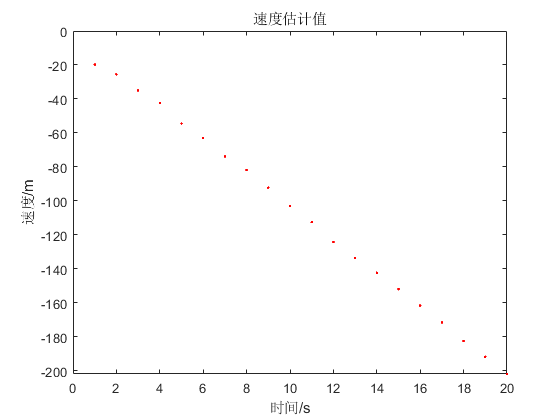

% 速度
figure;
plot(i1,XX(2,:),'r.'); %最后'r.'表示用红色(red)画点
xlabel('时间/s');ylabel('速度/m');
title('速度估计值');

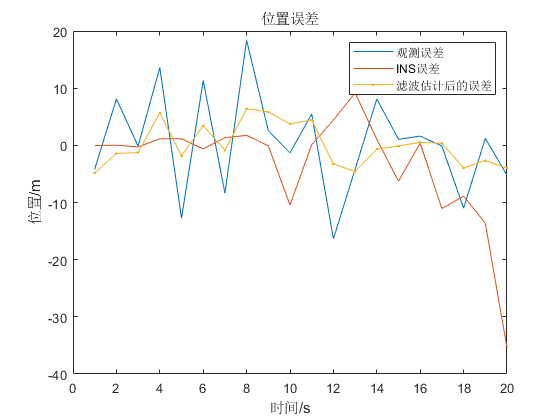


% 误差绘图
err_Z=Z-height;
err_INS = 2000-0.5*g_INS.*[1:20].^2-height;
err_est=XX(1,:)-height;
figure;
plot(i1,err_Z,i1,err_INS,i1,err_est,'.-'); %最后'.-'表示用默认颜色画带点的实现
xlabel('时间/s');ylabel('位置/m');
title('位置误差');
legend('观测误差','INS误差','滤波估计后的误差');

衡量指标：

绝对值：abs()，最大值：max()，平均值：mean()

max(abs(err_est))

ans =           6.41448635873417


mean(abs(err_est));